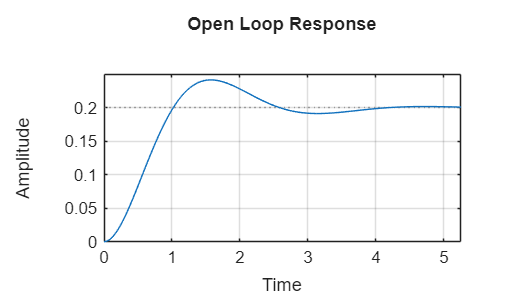

clc;
clear;
close all;

s = tf('s');

G = 1/(s^2 + 2*s + 5);

Kp = 40;
Ki = 25;
Kd = 12;
C = pid(Kp, Ki, Kd);

T = feedback(C*G, 1);

figure;
step(G);
grid on;
title('Open Loop Response');
saveas(gcf, 'open_loop_response.png');

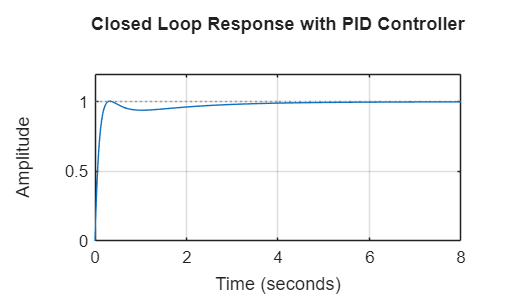


figure;
step(T);
grid on;
title('Closed Loop Response with PID Controller');
saveas(gcf, 'closed_loop_response.png');


info_open = stepinfo(G)

info_open = struct with fields:
         RiseTime: 0.6903
    TransientTime: 3.7352
     SettlingTime: 3.7352
      SettlingMin: 0.1830
      SettlingMax: 0.2416
        Overshoot: 20.7866
       Undershoot: 0
             Peak: 0.2416
         PeakTime: 1.5658


info_closed = stepinfo(T)

info_closed = struct with fields:
         RiseTime: 0.1530
    TransientTime: 2.8965
     SettlingTime: 2.8965
      SettlingMin: 0.9034
      SettlingMax: 1.0047
        Overshoot: 0.4684
       Undershoot: 0
             Peak: 1.0047
         PeakTime: 0.3272


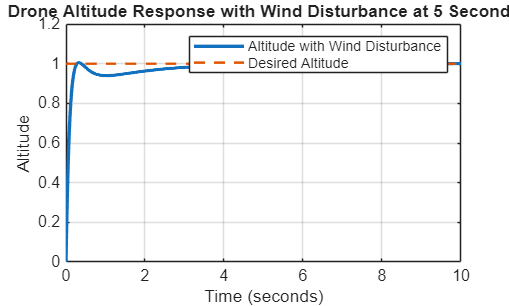


t = 0:0.01:10;
r = ones(size(t));

d = zeros(size(t));
d(t >= 5) = 0.2;

Td = feedback(G, C);

y_ref = lsim(T, r, t);
y_dist = lsim(Td, d, t);
y_total = y_ref + y_dist;

figure;
plot(t, y_total, 'LineWidth', 2);
grid on;
xlabel('Time (seconds)');
ylabel('Altitude');
title('Drone Altitude Response with Wind Disturbance at 5 Seconds');
hold on;
plot(t, r, '--', 'LineWidth', 1.5);
legend('Altitude with Wind Disturbance', 'Desired Altitude');
saveas(gcf, 'disturbance_response.png');